Fs=1000 %采样频率

Fs = 1000

t=0:1/Fs:1-1/Fs;

%定义信号
x=exp(-2*t).*sin(100*pi*t);

%FFT
N=length(x); %信号长度
Y=fft(x);

%计算双边频谱
P2=abs(Y)/N;
P1=P2(1:N/2+1);
P1(2:end-1)=2*P1(2:end-1)%取单边频率 分量*2

P1 =     0.0027    0.0055    0.0055    0.0055    0.0055    0.0055    0.0055    0.0056    0.0056    0.0056    0.0057    0.0057    0.0058    0.0059    0.0059    0.0060    0.0061    0.0062    0.0063    0.0064    0.0065    0.0066    0.0068    0.0069    0.0071    0.0073    0.0075    0.0077    0.0080    0.0082    0.0086    0.0089    0.0093    0.0097    0.0102    0.0107    0.0114    0.0121    0.0130    0.0140    0.0152    0.0167    0.0186    0.0211    0.0243    0.0289    0.0357    0.0470    0.0693    0.1324


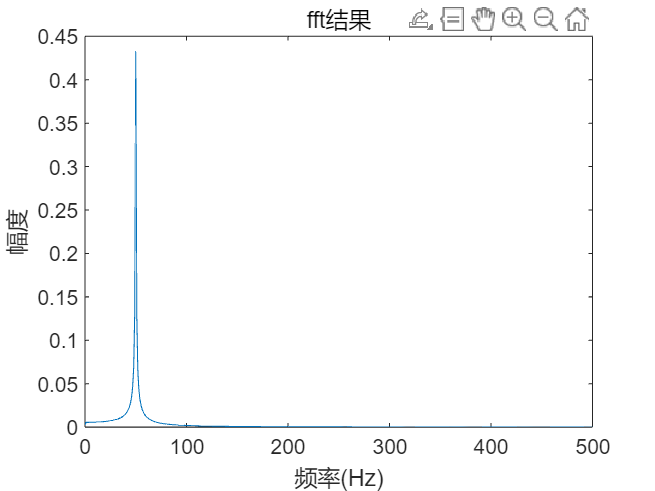


%频率轴
f=Fs*(0:(N/2))/N;

plot(f,P1);
title("fft结果");
xlabel('频率(Hz)')
ylabel('幅度')


phase=angle(Y)

phase =          0   -0.0003   -0.0005   -0.0008   -0.0010   -0.0013   -0.0016   -0.0018   -0.0021   -0.0024   -0.0027   -0.0030   -0.0033   -0.0036   -0.0039   -0.0042   -0.0046   -0.0049   -0.0053   -0.0057   -0.0061   -0.0065   -0.0070   -0.0075   -0.0080   -0.0085   -0.0091   -0.0098   -0.0104   -0.0112   -0.0120   -0.0129   -0.0139   -0.0150   -0.0162   -0.0175   -0.0191   -0.0209   -0.0230   -0.0254   -0.0284   -0.0319   -0.0364   -0.0421   -0.0497   -0.0603   -0.0762   -0.1025   -0.1547   -0.3051


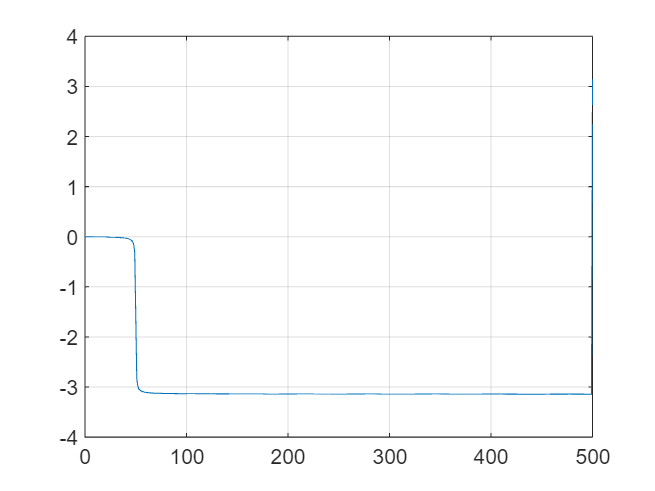

phase_one_side=phase(1:N/2+1);

plot(f,phase_one_side);
grid on

Fs=1000 %采样频率

Fs = 1000

t=0:1/Fs:1-1/Fs;
y=sin(3*pi*t)+2*sin(5*pi*t)

y =          0    0.0408    0.0817    0.1225    0.1633    0.2040    0.2447    0.2854    0.3260    0.3665    0.4070    0.4473    0.4876    0.5278    0.5679    0.6078    0.6476    0.6873    0.7268    0.7662    0.8054    0.8445    0.8833    0.9220    0.9605    0.9988    1.0369    1.0748    1.1124    1.1498    1.1870    1.2239    1.2605    1.2969    1.3331    1.3689    1.4045    1.4397    1.4747    1.5094    1.5437    1.5777    1.6114    1.6447    1.6778    1.7104    1.7427    1.7746    1.8062    1.8374




b=exp(-2*t)

b =     1.0000    0.9980    0.9960    0.9940    0.9920    0.9900    0.9881    0.9861    0.9841    0.9822    0.9802    0.9782    0.9763    0.9743    0.9724    0.9704    0.9685    0.9666    0.9646    0.9627    0.9608    0.9589    0.9570    0.9550    0.9531    0.9512    0.9493    0.9474    0.9455    0.9436    0.9418    0.9399    0.9380    0.9361    0.9343    0.9324    0.9305    0.9287    0.9268    0.9250    0.9231    0.9213    0.9194    0.9176    0.9158    0.9139    0.9121    0.9103    0.9085    0.9066


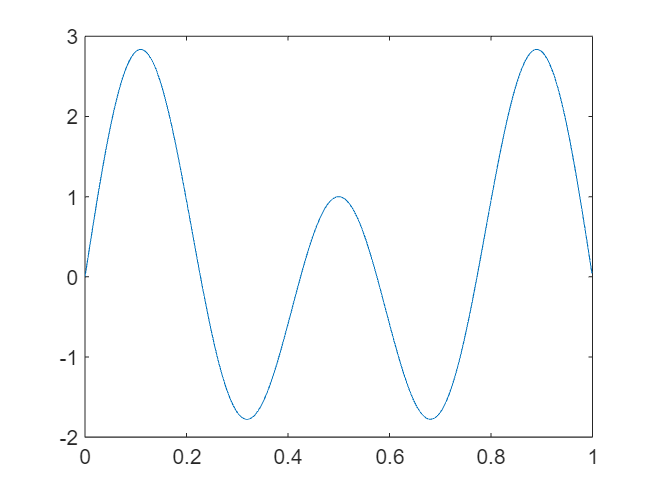


yy=y.*b;

plot(t,y)

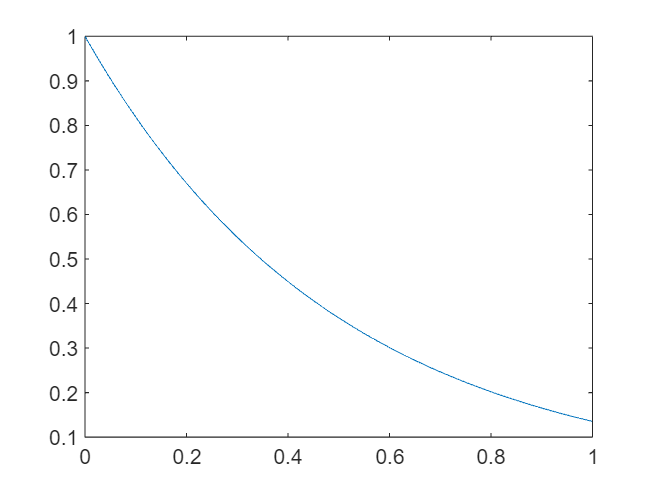

plot(t,b)

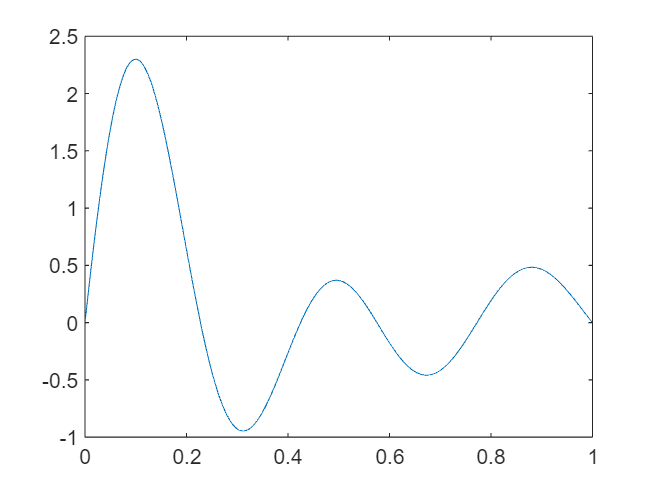

plot(t,yy)